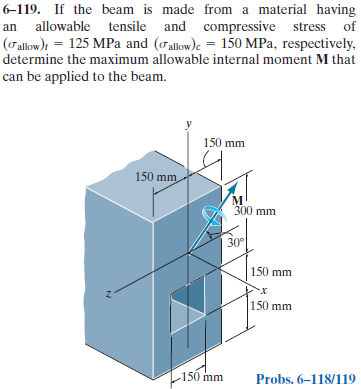

# symbolic units clas

u = symunit;

# section properties

% ------------------------------
% y-axis centroid
yc = [300; 150+150/2]*u.mm;
Acz = [300*600; -150*150]*u.mm^2;
Icz = [300*600^3; -150*150^3]/sym(12)*u.mm^4;
[yn Qnz Inz] = beam.neutral_axis(yc, Acz, Icz); %#ok
Iz = sum(Inz);
% ------------------------------
% z-axis centroid
zc = [0; 0];
Acy = [600*300; -150*150]*u.mm^2;
Icy = [600*300^3; -150*150^3]/sym(12)*u.mm^4;
[zn Qny Iny] = beam.neutral_axis(zc, Acy, Icy); %#ok
Iy = sum(Iny);
% ------------------------------

# bending moments

syms M;
theta = 30*u.deg;
My(M) = M*sin(theta);
Mz(M) = -M*cos(theta);

# bending locations

y_max = [600*u.mm-yn; 600*u.mm-yn; -yn; -yn];
z_max = [150; -150; -150; 150]*u.mm;

# allowable bending stresses

sigmat_allow = 125*u.MPa;
sigmac_allow = -150*u.MPa;

# maximum bending moment

M_max = sym.zeros(4,1);
sigma_max = cell(4,1);
valid_M = false(4,1);
for k = 1:4
  % ------------------------------
  Mt = solve(sigmat_allow == beam.unsymmetric(My, Mz, Iy, Iz, ...
                                              y_max(k), z_max(k)));
  Mc = solve(sigmac_allow == beam.unsymmetric(My, Mz, Iy, Iz, ...
                                              y_max(k), z_max(k)));
  M_max(k) = rewrite(symmax([Mt Mc]), u.kN*u.m);
  sigma_max{k} = rewrite(beam.unsymmetric(My(M_max(k)), Mz(M_max(k)), Iy, Iz, ...
                                          y_max, z_max), u.MPa);
  % ------------------------------
  pos_sigma_max = isAlways(sigma_max{k} > 0);
  neg_sigma_max = isAlways(sigma_max{k} < 0);
  valid_M(k) = all(isAlways(sigma_max{k}(pos_sigma_max) <= sigmat_allow)) && ...
               all(isAlways(sigma_max{k}(neg_sigma_max) >= sigmac_allow));
  % ------------------------------
end
clear k Mt Mc pos_sigma_max neg_sigma_max;

# bending moment limit

M_limit = M_max(valid_M);
M_limit_vpa = vpa(M_limit, 6) %#ok

$$M\_limit\_vpa = 1185.91\,\mathrm{kN}\,m$$

clear M_limit_vpa;
% ------------------------------